jd = juliandate(datetime('today'))

jd = 2.4603e+06

orbiting = 'Earth';
r_Sun = planetEphemeris(jd,orbiting,'Sun','432t','km');
r_Mercury = planetEphemeris(jd,orbiting,'Mercury','432t','km');
r_Venus = planetEphemeris(jd,orbiting,'Venus','432t','km');
r_Earth = planetEphemeris(jd,orbiting,'Earth','432t','km');
r_Moon = planetEphemeris(jd,'Earth','Moon','432t','km');
r_Mars = planetEphemeris(jd,orbiting,'Mars','432t','km');
r_Jupiter = planetEphemeris(jd,orbiting,'Jupiter','432t','km');
r_Saturn = planetEphemeris(jd,orbiting,'Saturn','432t','km');
r_Uranus = planetEphemeris(jd,orbiting,'Uranus','432t','km');
r_Neptune = planetEphemeris(jd,orbiting,'Neptune','432t','km');

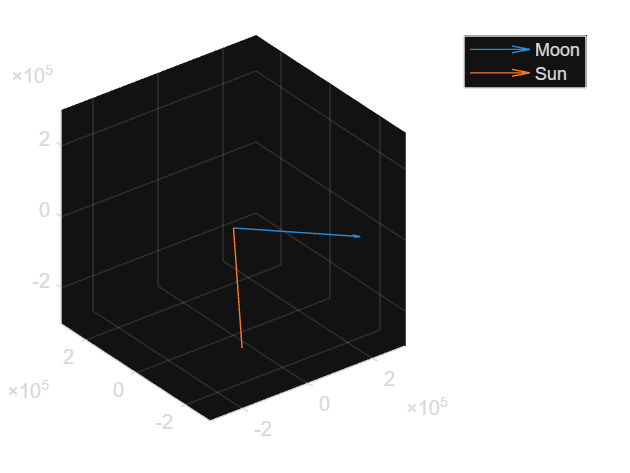

figure(1)
clf
% quiver3(0,0,0,r_Mercury(1),r_Mercury(2),r_Mercury(3),DisplayName='Mercury')
% quiver3(0,0,0,r_Venus(1),r_Venus(2),r_Venus(3),DisplayName='Venus')
% quiver3(0,0,0,r_Earth(1),r_Earth(2),r_Earth(3),DisplayName='Earth')
% quiver3(0,0,0,r_Mars(1),r_Mars(2),r_Mars(3),DisplayName='Mars')
% quiver3(0,0,0,r_Jupiter(1),r_Jupiter(2),r_Jupiter(3),DisplayName='Jupiter')
% quiver3(0,0,0,r_Saturn(1),r_Saturn(2),r_Saturn(3),DisplayName='Saturn')
% quiver3(0,0,0,r_Uranus(1),r_Uranus(2),r_Uranus(3),DisplayName='Uranus')
% quiver3(0,0,0,r_Neptune(1),r_Neptune(2),r_Neptune(3),DisplayName='Neptune')
quiver3(r_Earth(1),r_Earth(2),r_Earth(3),r_Moon(1),r_Moon(2),r_Moon(3),DisplayName='Moon')
hold on
quiver3(0,0,0,r_Sun(1),r_Sun(2),r_Sun(3),DisplayName='Sun')
legend
daspect([1 1 1])
lim = [-3e5 3e5];
xlim(lim)
ylim(lim)
zlim(lim)